# Pregunta 2

## Maximiliano Rivera

## Problema 2.1

- El costo de guardar cada elemento de A es de $m\cdot n$

- El costo de guardar cada término de la SVD,  es obtener todos los coeficientes de la sumatoria $\sum_{i = 1}^{n} \sigma_i u_i v_i^{*}$, dando un total de $(m+n +1)\cdot n$

- El costo de guardar un término de la SVD es de $m+n +1$, debido a que, con 1 término tenemos: $\sum_{i = 1}^{1} \sigma_i u_i v_i^{*}$, con $u_i$ de largo m, $v_i$largo n, y $ \sigma_i $es un escalar.

- El costo de guardar $k$elementos de la SVD es igual a $(m+n +1)\cdot k$, por ende, el $k$para que se almacene la misma cantidad de información es $k = \frac{m\cdot n}{m+n+1}$. Esto significa que, utilizando ese $k$, la descomposicion SVD presenta la misma información que la matriz previa.

- El error relativo asociado a la imagen con k-términos es $\sum_{i = k+1}^{n} \sigma_i u_i v_i^{*}$

##  Problema 2.2

a) Se crea una matriz $C \in C^{10x10x3}$, para luego encontrar la escala de grises la imagen, quedando $C_{gray} \in C^{10x10}$

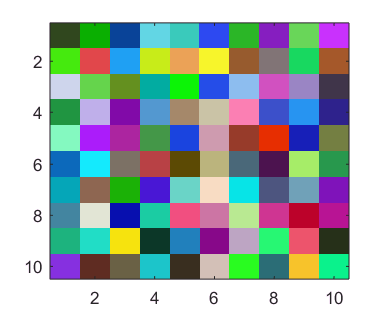

C = rand(10, 10, 3);
image(C); 

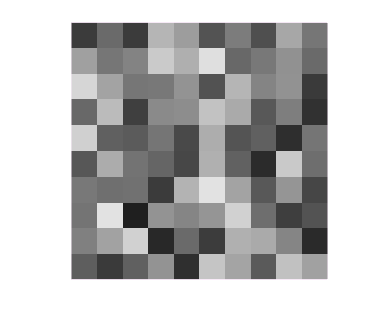

Cgray = rgb2gray(C);
% Cgray = rand(10, 10);
% imshow(Cgray 'CDataMapping','scaled'); colorbar;
% fig = figure();
% ax = axes(fig);
magnification = 6000;
imshow(Cgray, 'InitialMagnification', magnification);

b) Se descompone la matriz $C_{gray}$ según la SVD.

[U,S,V] = svd(Cgray);
% image(U*S*V', 'CDataMapping','scaled'); colorbar; 
imshow(U*S*V', 'InitialMagnification', magnification);

c) Se estima el k y luego se calcula el SVD para los primeros k términos.

[m, n] = size(Cgray);

k = 5

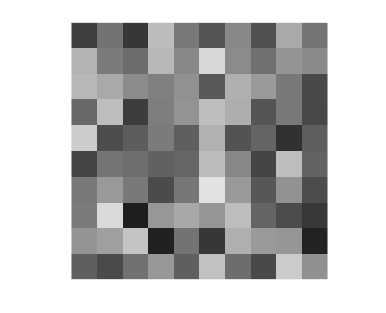

k = round(m*n/(m + n+ 1)) 
Sk = S(1:k, 1:k);
Uk = U(:, 1:k);
Vk = V(:, 1:k);
Cgray2 = Uk*Sk*Vk';
% image(Cgray2, 'CDataMapping','scaled'); colorbar; 

imshow(Cgray2, 'InitialMagnification', magnification);

En esta última figura podemos notar que al utilizar una cantidad de valores singulares reducidos, la matriz resultante es levemente diferente a la matriz original. Esto se debe a la aproximaxión previamente calculada.

## Problema 2.3

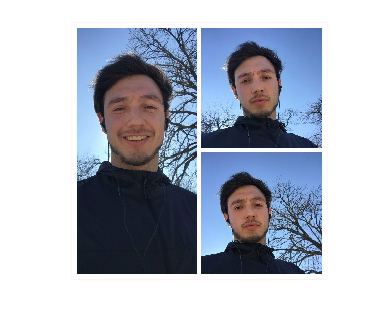

Max = im2double(imread('max.bmp'));
imshow(Max)

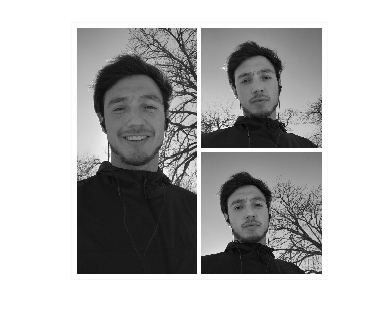

magnification2 = 100;
 Igray = rgb2gray(Max);
imshow(Igray, 'InitialMagnification', magnification2);

b) Descomposición SVD:

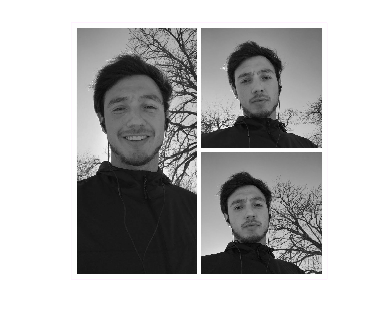

% Igray_double = double(Igray);
[UI,SI,VI] = svd(Igray);
% image(U*S*V', 'CDataMapping','scaled'); colorbar; 
imshow(UI*SI*VI', []);

c) 

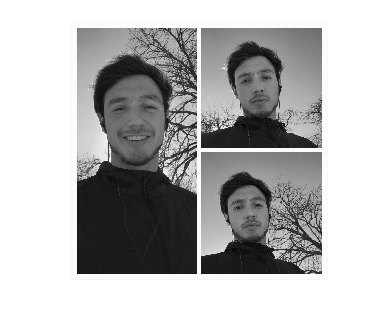

[m, n] = size(Igray);
k = round(m*n/(m + n+ 1)); 
% k=300;
SIk = SI(1:k, 1:k);
UIk = UI(:, 1:k);
VIk = VI(:, 1:k);
Igray2 = UIk*SIk*VIk';
% image(Cgray2, 'CDataMapping','scaled'); colorbar; 
imshow(Igray2, []);

## Problema 2.4

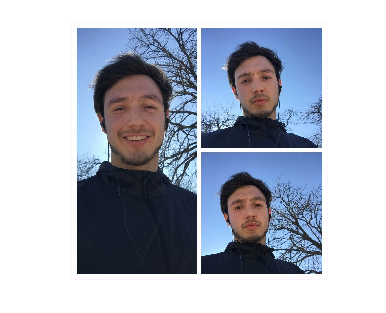

Max1 = Max(:, :, 1);
Max2 = Max(:, :, 2);
Max3 = Max(:, :, 3);
% Igray_double = double(Igray);
[U1,S1,V1] = svd(Max1);
[U2,S2,V2] = svd(Max2);
[U3,S3,V3] = svd(Max3);
% image(U*S*V', 'CDataMapping','scaled'); colorbar; 
[m, n] = size(Max1);
k = round(m*n/(m + n+ 1)); 
S1k = S1(1:k, 1:k);
U1k = U1(:, 1:k);
V1k = V1(:, 1:k);
S2k = S2(1:k, 1:k);
U2k = U2(:, 1:k);
V2k = V2(:, 1:k);
S3k = S3(1:k, 1:k);
U3k = U3(:, 1:k);
V3k = V3(:, 1:k);
NewMax = zeros(m, n, 3);
NewMax(:,:,1) = U1k*S1k*V1k';
NewMax(:,:,2) = U2k*S2k*V2k';
NewMax(:,:,3) = U3k*S3k*V3k';
imshow(NewMax)